%%%%%%%%%%%%%%%%%%%%
% MT practice 3 ELEC 341
%
% Author: YI-CHEN LIN

%%%%%%%%%%%%%%%%%%%%

clear all;
clc;

SN = 48861785;

syms s U Y A;

G1 = (4+10)/(s+(8+10));
G2 = (10*s+(8+10)+30)/(s+(6+10)+30);

H1 = (20*s+(1+10)+20)/(s+(7+10)+20);
H2 = (30*s+(8+10)+10)/(s+(5+10)+10);


eq1 = (U-A-(Y*H1))*G1 == Y;
eq2 = (Y-A*G2)*H2 == A;

aa = solve(eq2,A);
aa

$$aa = \frac{30\,Y\,s^{2}+1408\,Y\,s+1288\,Y}{301\,s^{2}+1791\,s+2494}$$

A = aa;
A

$$A = \frac{30\,Y\,s^{2}+1408\,Y\,s+1288\,Y}{301\,s^{2}+1791\,s+2494}$$


eq1 = (U-A-(Y*H1))*G1 == Y;

yy = solve(eq1,Y);
tfG1 = yy/U;

tfG1s = simplify(tfG1);

[num, den] = numden(tfG1s);

clear s;

s = tf("s");

tfG1sf = tf(sym2poly(num), sym2poly(den));
tfG1sf

tfG1sf =
 
         4214 s^3 + 180992 s^2 + 962654 s + 1.292e06
  ---------------------------------------------------------
  301 s^4 + 103046 s^3 + 968831 s^2 + 3.553e06 s + 3.411e06
 
Continuous-time transfer function.
Model Properties


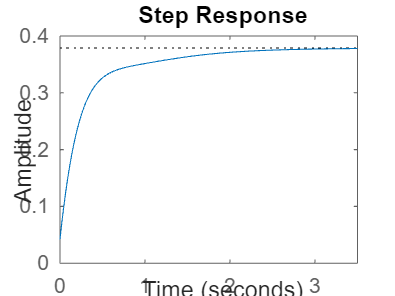

Q1.G = tfG1sf;
Q1.G = tf([ 14 601.3 3198 4292],[1 342.3 3219 1.18e04 1.133e04]);

%Q1.G
poles = pole(Q1.G);
zeros = zero(Q1.G);

[~, sortedIndices] = sort(abs(real(poles)));
sorted_poles = poles(sortedIndices);

% Identify most dominant, dominant, and non-dominant poles
most_dominant_pole = sorted_poles(1);
dominant_poles = sorted_poles(2:end);


poles = pole(Q1.G);
zeros = zero(Q1.G);

numerator_r = [-2.223 -3.727 -37]; 
denominator_r = [-1.438 -4.06+2.68i -4.06-2.68i];

G_r = zpk(numerator_r, denominator_r,1);
%G_r = Q1.G;
Q2.p = denominator_r;
Q2.z = numerator_r;
Q2.Gr = G_r*dcgain(Q1.G)/dcgain(G_r);


%Q3.Ga =getFirstApprox(Q2.Gr);





step(Q2.Gr)

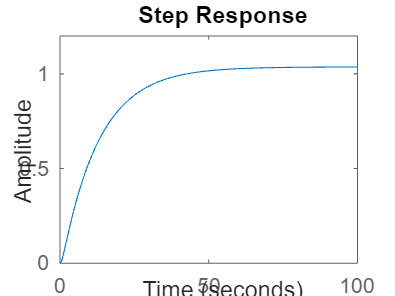

Q3.Ga = (80/13)/(s+1/13);

ce = 1 + 162/((8+10)*s*(s+6)+(s+3)^2);
ce;

Q5.K = 162;
Q5.wn = 3;
Q5.Tr1 = 1.1; % guess

zeta = (Q5.Tr1*Q5.wn+1.15)/4.44;

Q5.taue = 1.83*Q5.Tr1*zeta/2.86;

M = (4+10);
B = (8+10);
K = (8+10);
n = (6+10)/5;
F2 = (7+10)*n;

BM = B*n^2;
KM = K*n^2;
MM = M*n^2;


R = 1/B;
L = 1/K;
CM = MM;
RM = 1/BM;
LM = 1/KM;

Zr = R;
Zl = L*s;
ZcM = 1/(CM*s);
ZrM = RM;
ZlM = LM*s;

Zt1 = Zr*Zl/(Zr+Zl)+ZlM;

Zt2 = 1/Zt1 + 1/ZcM+ 1/ZrM;
Zt2 = 1/Zt2;

% USE THE RR FUNCTION FOR PARALLELE RESISTORS WORKSSSSSSSS
Zt2 = RR(RR(Zl,Zr)+ZlM,RR(ZcM,ZrM));

irt = F2*Zt2/(Zt2+Zr);

ff = (irt)*(Zt2+Zr)/Zt2;

v1 = irt*Zr;

Q6.Y1 = v1/ff;



Zt3 = RR(Zt2,Zr);
v1 = Zt3*F2/(s*n);
step(v1)

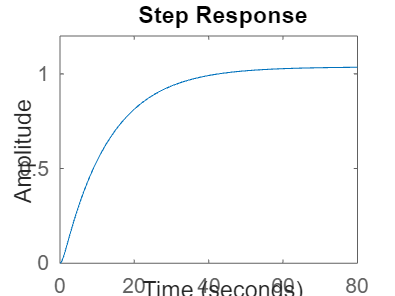


Q6.yf = Q6.Y1*F2/(s*n);
step(Q6.yf)

Q6.yf = dcgain(Q6.yf);
Q6.yf = 0.57*1000;
run m3Submit.p;



function eq = RR(z1, z2)
    eq = (z1 * z2 ) / (z1 + z2);
end









































function approx = getFirstApprox(G, scale)
    if ~exist('scale','var')
     % third parameter does not exist, so default it to something
      scale = 10;
    end
    s = tf('s');
    tau = getTau(G, scale);
    a = 1/tau;
    k = dcgain(G) * a;
    approx = k/(s+a);
end

function tau = getTau(G, scale)
    if ~exist('scale','var')
     % third parameter does not exist, so default it to something
      scale = 10;
    end
    [v,t] = step(G, scale);
    fv = v(end);
    tau = 0;
    for n = 1 : length(v)
        val = v(n);
        ratio = val/fv;
        if ratio >= 0.632
            tau = t(n);
            break
        end
    end
end